# **Stanford Manipulator**

clc; clear; close all

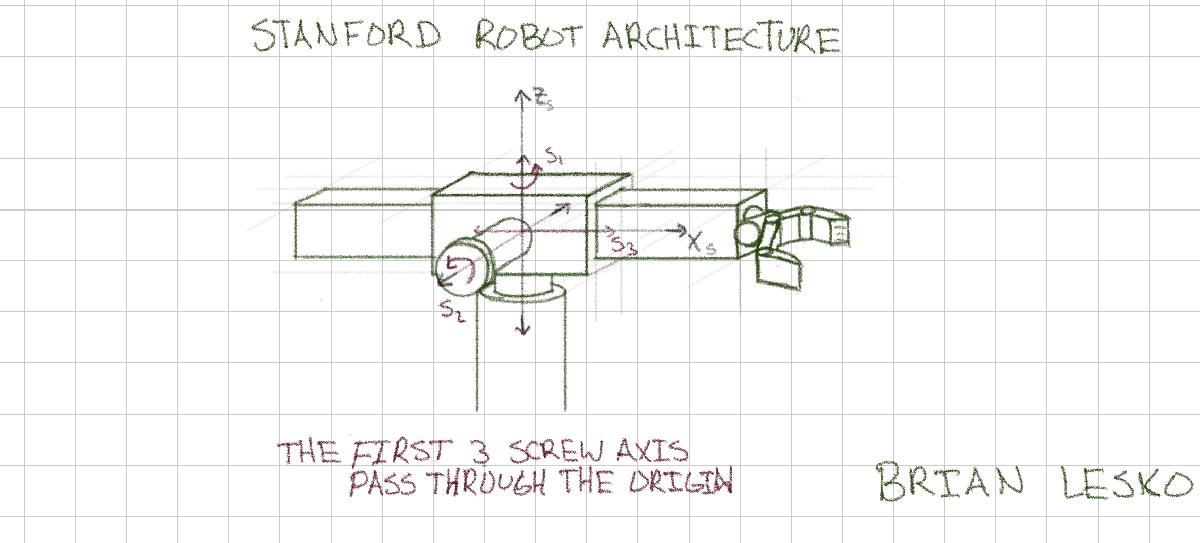

Generate a Trajectory from one end effector position to another (with a constant screw axis) and check that the trajectory satisfies joint limits. Find the joint forces and torques needed to command the robot to follow this trajectory. No feedback.

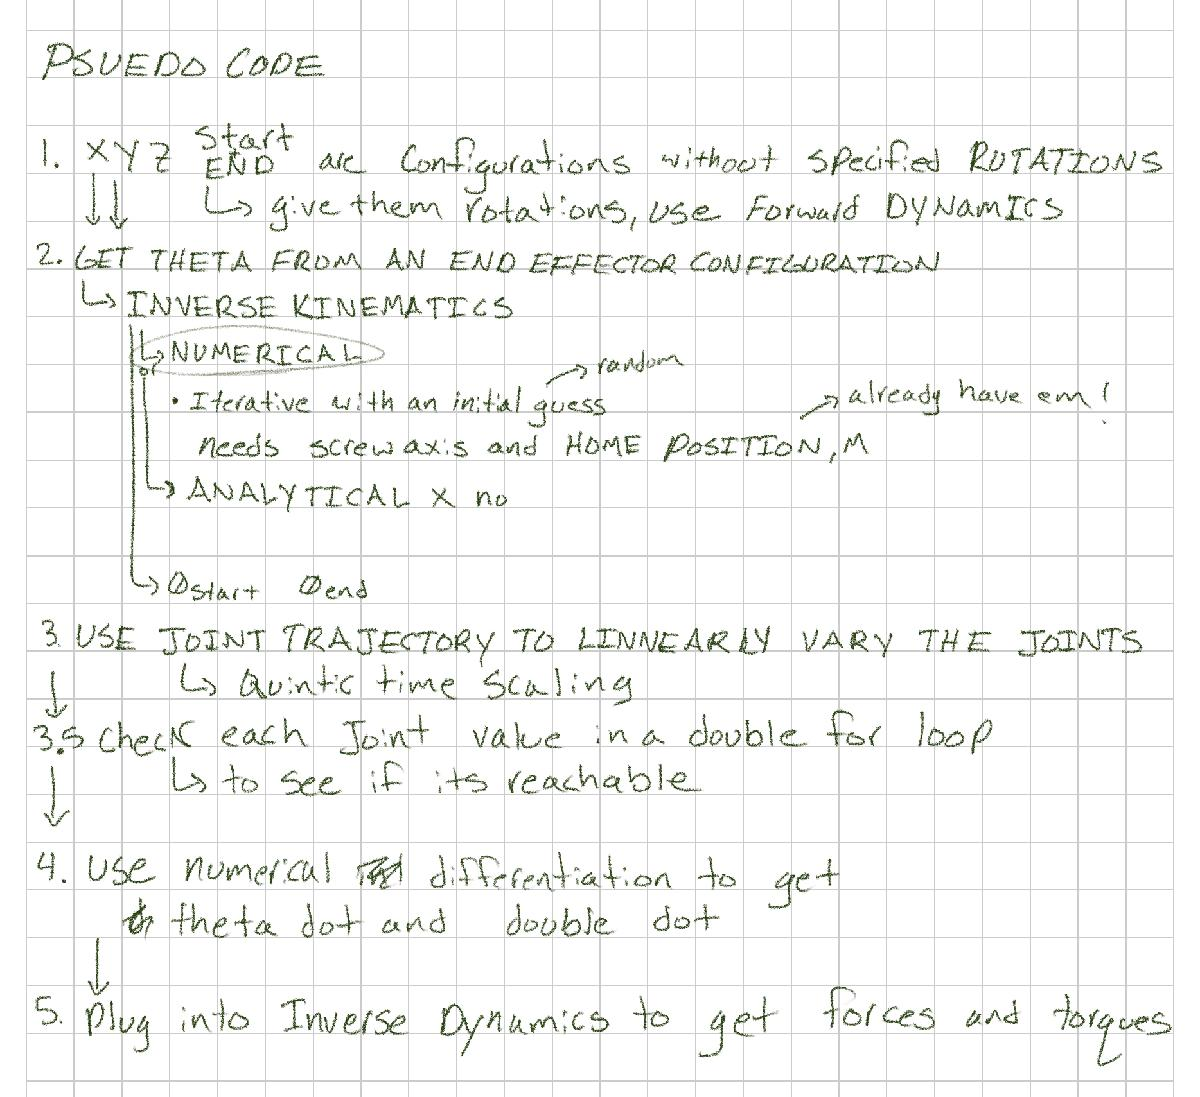

Link Information 

%mass, m in  kg
%rx ry rz in m
L1.m = 9; L1.rx = 0; L1.ry = -0.1; L1.rz = 0; 
L2.m = 6; L2.rx = 0; L2.ry = 0; L2.rz = 0; 
L3.m = 4; L3.rx = 0; L3.ry = 0; L3.rz = 0; 
L1.Ixx = 0.01; L1.Iyy = 0.02; L1.Izz = 0.01;
L2.Ixx = 0.05; L2.Iyy = 0.06; L2.Izz = 0.01;
L3.Ixx = 0.4; L3.Iyy = 0.4; L3.Izz = 0.01;

Glist: Spatial inertia matrices Gi of the links

Ib1 = [[L1.Ixx 0 0];[0 L1.Iyy 0];[0 0 L1.Izz]];
Ib2 = [[L2.Ixx 0 0];[0 L2.Iyy 0];[0 0 L2.Izz]];
Ib3 = [[L3.Ixx 0 0];[0 L3.Iyy 0];[0 0 L3.Izz]];
G1 = [Ib1 zeros(3,3) ; zeros(3,3) L1.m*eye(3)]; %6by6
G2 = [Ib2 zeros(3,3) ; zeros(3,3) L2.m*eye(3)]; %6by6
G3 = [Ib3 zeros(3,3) ; zeros(3,3) L3.m*eye(3)]; %6by6
Glist = cat(3, G1, G2, G3);

Mlist: list of link frames i relative to i-1 at the home position

%Given for the Link Frames
W1 = 0.1;
M01 = eye(4); 
M12 = [[1 0 0 0];[0 0 -1 W1];[0 1 0 0];[0 0 0 1]];
M23 = [[0 0 1 0];[0 -1 0 W1];[1 0 0 0];[0 0 0 1]];
Mend = [eye(3) [0 0 0]'; zeros(1,3) 1];
Mlist = cat(3, M01, M12, M23, Mend );

%The home configuration is different
M = Mend;

Slist: The screw axis of each joint i

S1 = [0 0 1 0 0 0]'; S2 = [0 -1 0 0 0 0]'; S3 = [0 0 0 1 0 0]';
Slist = [S1 S2 S3];

**Inverse Kinematics**

**thetaStart from a chosen start configuration **

Tstart = FKinSpace(M,Slist,[0 0 0.1]'*pi/180)

Tstart =     1.0000         0         0    0.0017
         0    1.0000         0         0
         0         0    1.0000         0
         0         0         0    1.0000


thetaGuess = [rand(1) rand(1) rand(1)]';
[thetaStart, success] = IKinSpace(Slist, M, Tstart, thetaGuess, 0.005, 0.005)

thetaStart =     0.0009
    0.0035
    0.0057


success = logical
   1


thetaEnd from a chosen end configuration 

Tend = FKinSpace(M,Slist,[90 45 0.74]'*pi/180)

Tend =     0.0000   -1.0000   -0.0000    0.0000
    0.7071    0.0000   -0.7071    0.0091
    0.7071         0    0.7071    0.0091
         0         0         0    1.0000


thetaGuess = [rand(1) rand(1) rand(1)]';
[thetaEnd, success] = IKinSpace(Slist, M, Tend, thetaGuess, 0.005, 0.005)

thetaEnd =     1.5708
    0.7854
    0.0129


success = logical
   1


Straight Line Joint Space Trajectory from thetaStart to thetaEnd

theta_difference = abs(thetaStart - thetaEnd);
theta_difference_squared = theta_difference' * theta_difference;
totalTime = 10*theta_difference_squared; 
N = round(totalTime,0); %1 positon calc per second

method = 5;
traj = JointTrajectory(thetaStart, thetaEnd, totalTime, N, method)

traj =     0.0009    0.0035    0.0057
    0.0014    0.0038    0.0057
    0.0051    0.0056    0.0057
    0.0143    0.0102    0.0057
    0.0311    0.0185    0.0058
    0.0566    0.0312    0.0059
    0.0918    0.0488    0.0061
    0.1370    0.0713    0.0063
    0.1922    0.0988    0.0065
    0.2569    0.1310    0.0068


Check the Joint Limits at each position on the Path

limits.upper = [160 110 0.75];
limits.lower = [-160 -20 0.1];

within_joint_limits = zeros(1,N); %Initialize
for t = 1:1:N
    for j = 1:1:length(traj(1,:))
        joints_now = traj(t,:)*180/pi;
        if (joints_now(j) >= limits.lower(j)) && (joints_now(j)<=limits.upper(j))
            within_joint_limits(t) = 1; 
        else 
            within_joint_limits(t) = 0; 
        end 
    end 
end 
if sum(within_joint_limits) == N
    disp('This Path is within the joint limits')
else
    disp('This Path is NOT within the joint limits')
end 

This Path is within the joint limits


Computing the Joint Torques and Forces needed at each timestep to achieve the trajectory

th_d = [rand(1) rand(1) rand(1)]'; %theta dot vector
th_dd = [rand(1) rand(1) rand(1)]'; %theta double dot vector
g = [0 0 -9.81]';
Ftip = [0 0 0 0 0 0]';

th_dMat = zeros(N,3); th_ddMat = zeros(N,3);
tauMat = zeros(N,6); %Initialize 
for t = 1:1:N
    th = traj(t,:);
    %Numerical Integration is sexy
    if t<N
        dt = totalTime/N;
        th_d = ( traj(t+1,:) - traj(t,:) )/ dt; %Forward Difference
        th_dMat(t,:) = th_d;
        if t<N-1 %Second Order
        th_dd = ( traj(t+2,:) - 2*traj(t+1,:) + traj(t,:) )/ dt^2; %Second Order Forward Difference
        th_ddMat(t,:) = th_dd;
        end 
    end 
    taulist = InverseDynamics(th,th_d,th_dd,g, Ftip, Mlist, Glist, Slist);
    tauMat(t,:) = taulist';
end 
tauMat

tauMat = 1.0e-03 *

    0.0314    0.0314    0.0314    0.0314    0.0314    0.0314
    0.0568    0.0568    0.0568    0.0568    0.0568    0.0568
    0.0761    0.0761    0.0761    0.0761    0.0761    0.0761
    0.0896    0.0896    0.0896    0.0896    0.0896    0.0896
    0.0980    0.0980    0.0980    0.0980    0.0980    0.0980
    0.1017    0.1017    0.1017    0.1017    0.1017    0.1017
    0.1011    0.1011    0.1011    0.1011    0.1011    0.1011
    0.0967    0.0967    0.0967    0.0967    0.0967    0.0967
    0.0891    0.0891    0.0891    0.0891    0.0891    0.0891
    0.0785    0.0785    0.0785    0.0785    0.0785    0.0785


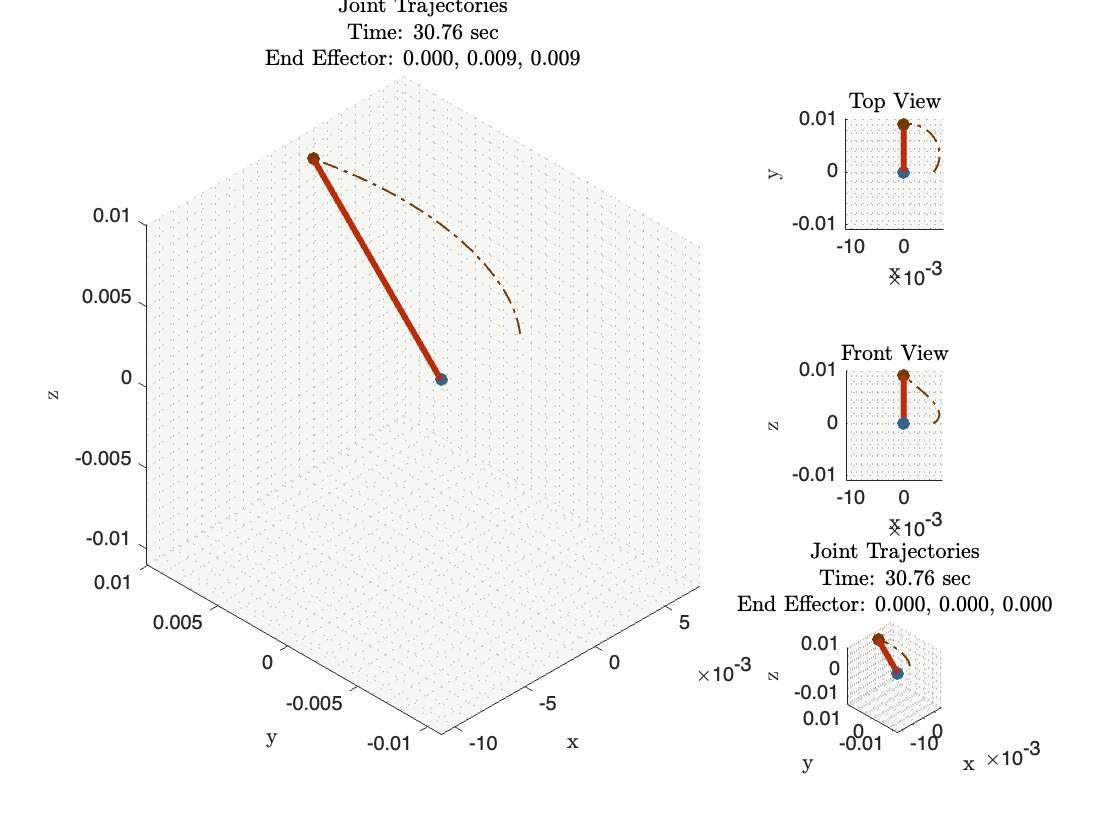

M01 = [[eye(3),[0 0 0]'];[0 0 0 1]];
M02 = [[eye(3),[0 0 0]'];[0 0 0 1]];
M03 = [[eye(3),[0 0 0]'];[0 0 0 1]];
Mlist_joints = cat(3,M01,M02,M03);
saveTo_gif = 'animation.gif';
Mlist_links = Mlist;
animateRobot(traj,totalTime,Glist,Slist,Mlist_links,Mlist_joints,saveTo_gif)

Modern Robotics Functions 

function T = FKinSpace(M, Slist, thetalist)
% *** CHAPTER 4: FORWARD KINEMATICS ***
% Takes M: the home configuration (position and orientation) of the 
%          end-effector,
%       Slist: The joint screw axes in the space frame when the manipulator
%              is at the home position,
%       thetalist: A list of joint coordinates.
% Returns T in SE(3) representing the end-effector frame, when the joints 
% are at the specified coordinates (i.t.o Space Frame).
T = M;
for i = size(thetalist): -1: 1
    T = MatrixExp6(VecTose3(Slist(:, i) * thetalist(i))) * T;
end
end
function se3mat = VecTose3(V)
% *** CHAPTER 3: RIGID-BODY MOTIONS ***
% Takes a 6-vector (representing a spatial velocity).
% Returns the corresponding 4x4 se(3) matrix.
se3mat = [VecToso3(V(1: 3)), V(4: 6); 0, 0, 0, 0];
end
function omg = so3ToVec(so3mat)
% *** CHAPTER 3: RIGID-BODY MOTIONS ***
% Takes a 3x3 skew-symmetric matrix (an element of so(3)).
% Returns the corresponding 3-vector (angular velocity).
omg = [so3mat(3, 2); so3mat(1, 3); so3mat(2, 1)];
end
function so3mat = VecToso3(omg)
% *** CHAPTER 3: RIGID-BODY MOTIONS ***
% Takes a 3-vector (angular velocity).
% Returns the skew symmetric matrix in so(3).
so3mat = [0, -omg(3), omg(2); omg(3), 0, -omg(1); -omg(2), omg(1), 0];
end
function T = MatrixExp6(se3mat)
% *** CHAPTER 3: RIGID-BODY MOTIONS ***
% Takes a se(3) representation of exponential coordinates.
% Returns a T matrix in SE(3) that is achieved by traveling along/about the 
% screw axis S for a distance theta from an initial configuration T = I.
omgtheta = so3ToVec(se3mat(1: 3, 1: 3));
if NearZero(norm(omgtheta))
    T = [eye(3), se3mat(1: 3, 4); 0, 0, 0, 1];
else
    [omghat, theta] = AxisAng3(omgtheta);
    omgmat = se3mat(1: 3, 1: 3) / theta; 
    T = [MatrixExp3(se3mat(1: 3, 1: 3)), ...
         (eye(3) * theta + (1 - cos(theta)) * omgmat ...
          + (theta - sin(theta)) * omgmat * omgmat) ...
            * se3mat(1: 3, 4) / theta;
         0, 0, 0, 1];
end
end
function judge = NearZero(near)
% *** BASIC HELPER FUNCTIONS ***
% Takes a scalar.
% Checks if the scalar is small enough to be neglected.
% Example Input:
judge = norm(near) < 1e-6;
end
function [thetalist, success] ...
         = IKinSpace(Slist, M, T, thetalist0, eomg, ev)
% *** CHAPTER 6: INVERSE KINEMATICS ***
% Takes Slist: The joint screw axes in the space frame when the manipulator
%              is at the home position, in the format of a matrix with the
%              screw axes as the columns,
%       M: The home configuration of the end-effector,
%       T: The desired end-effector configuration Tsd,
%       thetalist0: An initial guess of joint angles that are close to 
%                   satisfying Tsd,
%       eomg: A small positive tolerance on the end-effector orientation 
%             error. The returned joint angles must give an end-effector 
%             orientation error less than eomg,
%       ev: A small positive tolerance on the end-effector linear position 
%           error. The returned joint angles must give an end-effector 
%           position error less than ev.
% Returns thetalist: Joint angles that achieve T within the specified 
%                    tolerances,
%         success: A logical value where TRUE means that the function found
%                  a solution and FALSE means that it ran through the set 
%                  number of maximum iterations without finding a solution
%                  within the tolerances eomg and ev.
% Uses an iterative Newton-Raphson root-finding method.
% The maximum number of iterations before the algorithm is terminated has 
% been hardcoded in as a variable called maxiterations. It is set to 20 at 
% the start of the function, but can be changed if needed.  
thetalist = thetalist0;
i = 0;
maxiterations = 20;
Tsb = FKinSpace(M, Slist, thetalist);
Vs = Adjoint(Tsb) * se3ToVec(MatrixLog6(TransInv(Tsb) * T));
err = norm(Vs(1: 3)) > eomg || norm(Vs(4: 6)) > ev;
while err && i < maxiterations
    thetalist = thetalist + pinv(JacobianSpace(Slist, thetalist)) * Vs;
    i = i + 1;
    Tsb = FKinSpace(M, Slist, thetalist);
    Vs = Adjoint(Tsb) * se3ToVec(MatrixLog6(TransInv(Tsb) * T));
    err = norm(Vs(1: 3)) > eomg || norm(Vs(4: 6)) > ev;
end
success = ~ err;
end
function [omghat, theta] = AxisAng3(expc3)
% *** CHAPTER 3: RIGID-BODY MOTIONS ***
% Takes A 3-vector of exponential coordinates for rotation.
% Returns the unit rotation axis omghat and the corresponding rotation 
% angle theta.
theta = norm(expc3);
omghat = expc3 / theta;
end
function  R = MatrixExp3(so3mat)
% *** CHAPTER 3: RIGID-BODY MOTIONS ***
% Takes a 3x3 so(3) representation of exponential coordinates.
% Returns R in SO(3) that is achieved by rotating about omghat by theta 
% from an initial orientation R = I.
omgtheta = so3ToVec(so3mat);
if NearZero(norm(omgtheta))
    R = eye(3);
else
    [omghat, theta] = AxisAng3(omgtheta);
    omgmat = so3mat / theta;
    R = eye(3) + sin(theta) * omgmat + (1 - cos(theta)) * omgmat * omgmat;
end
end
function V = se3ToVec(se3mat)
% *** CHAPTER 3: RIGID-BODY MOTIONS ***
% Takes se3mat a 4x4 se(3) matrix
% Returns the corresponding 6-vector (representing spatial velocity).
V = [se3mat(3, 2); se3mat(1, 3); se3mat(2, 1); se3mat(1: 3, 4)];
end
function AdT = Adjoint(T)
% *** CHAPTER 3: RIGID-BODY MOTIONS ***
% Takes T a transformation matrix SE3. 
% Returns the corresponding 6x6 adjoint representation [AdT].
[R, p] = TransToRp(T);
AdT = [R, zeros(3); VecToso3(p) * R, R];
end
function [R, p] = TransToRp(T)
% *** CHAPTER 3: RIGID-BODY MOTIONS ***
% Takes the transformation matrix T in SE(3) 
% Returns R: the corresponding rotation matrix
%         p: the corresponding position vector .
R = T(1: 3, 1: 3);
p = T(1: 3, 4);
end
function invT = TransInv(T)
% *** CHAPTER 3: RIGID-BODY MOTIONS ***
% Takes a transformation matrix T.
% Returns its inverse. 
[R, p] = TransToRp(T);
invT = [transpose(R), -transpose(R) * p; 0, 0, 0, 1];
end
function expmat = MatrixLog6(T)
% *** CHAPTER 3: RIGID-BODY MOTIONS ***
% Takes a transformation matrix T in SE(3).
% Returns the corresponding se(3) representation of exponential 
% coordinates.
[R, p] = TransToRp(T);
omgmat = MatrixLog3(R);
if isequal(omgmat, zeros(3))
    expmat = [zeros(3), T(1: 3, 4); 0, 0, 0, 0];
else
    theta = acos((trace(R) - 1) / 2);
    expmat = [omgmat, (eye(3) - omgmat / 2 ...
                      + (1 / theta - cot(theta / 2) / 2) ...
                        * omgmat * omgmat / theta) * p;
              0, 0, 0, 0];    
end
end
function so3mat = MatrixLog3(R)
% *** CHAPTER 3: RIGID-BODY MOTIONS ***
% Takes R (rotation matrix).
% Returns the corresponding so(3) representation of exponential 
% coordinates.
acosinput = (trace(R) - 1) / 2;
if acosinput >= 1
    so3mat = zeros(3);
elseif acosinput <= -1
    if ~NearZero(1 + R(3, 3))
        omg = (1 / sqrt(2 * (1 + R(3, 3)))) ...
              * [R(1, 3); R(2, 3); 1 + R(3, 3)];
    elseif ~NearZero(1 + R(2, 2))
        omg = (1 / sqrt(2 * (1 + R(2, 2)))) ...
              * [R(1, 2); 1 + R(2, 2); R(3, 2)];
    else
        omg = (1 / sqrt(2 * (1 + R(1, 1)))) ...
              * [1 + R(1, 1); R(2, 1); R(3, 1)];
    end
    so3mat = VecToso3(pi * omg);
else
	theta = acos(acosinput);
    so3mat = theta * (1 / (2 * sin(theta))) * (R - R');
end
end
function Js = JacobianSpace(Slist, thetalist)
% *** CHAPTER 5: VELOCITY KINEMATICS AND STATICS ***
% Takes Slist: The joint screw axes in the space frame when the manipulator
%              is at the home position, in the format of a matrix with the
%              screw axes as the columns,
%       thetalist: A list of joint coordinates. 
% Returns the corresponding space Jacobian (6xn real numbers).
Js = Slist;
T = eye(4);
for i = 2: length(thetalist)
    T = T * MatrixExp6(VecTose3(Slist(:, i - 1) * thetalist(i - 1)));
	Js(:, i) = Adjoint(T) * Slist(:, i);
end
end
function traj = JointTrajectory(thetastart, thetaend, Tf, N, method)
% *** CHAPTER 9: TRAJECTORY GENERATION ***
% Takes thetastart: The initial joint variables,
%       thetaend: The final joint variables,
%       Tf: Total time of the motion in seconds from rest to rest,
%       N: The number of points N > 1 (Start and stop) in the discrete 
%          representation of the trajectory,
%       method: The time-scaling method, where 3 indicates cubic 
%               (third-order polynomial) time scaling and 5 indicates 
%               quintic (fifth-order polynomial) time scaling.
% Returns traj: A trajectory as an N x n matrix, where each row is an
%               n-vector of joint variables at an instant in time. The 
%               first row is thetastart and the Nth row is thetaend . The 
%               elapsed time between each row is Tf/(N - 1).
% The returned trajectory is a straight-line motion in joint space.
timegap = Tf / (N - 1);
traj = zeros(size(thetastart, 1), N);
for i = 1: N
    if method == 3
        s = CubicTimeScaling(Tf, timegap * (i - 1));
    else
        s = QuinticTimeScaling(Tf, timegap * (i - 1));
    end
    traj(:, i) = thetastart + s * (thetaend - thetastart);
end
traj = traj';
end
function s = QuinticTimeScaling(Tf, t)
% *** CHAPTER 9: TRAJECTORY GENERATION ***
% Takes Tf: Total time of the motion in seconds from rest to rest,
%       t: The current time t satisfying 0 < t < Tf.
% Returns s: The path parameter s(t) corresponding to a fifth-order
%            polynomial motion that begins and ends at zero velocity and 
%            zero acceleration.
s = 10 * (t / Tf) ^ 3 - 15 * (t / Tf) ^ 4 + 6 * (t / Tf) ^ 5;
end
function taulist = InverseDynamics(thetalist, dthetalist, ddthetalist, ...
                                   g, Ftip, Mlist, Glist, Slist)
% *** CHAPTER 8: DYNAMICS OF OPEN CHAINS ***
% Takes thetalist: n-vector of joint variables,
%       dthetalist: n-vector of joint rates,
%       ddthetalist: n-vector of joint accelerations,
%       g: Gravity vector g,
%       Ftip: Spatial force applied by the end-effector expressed in frame 
%             {n+1},
%       Mlist: List of link frames {i} relative to {i-1} at the home 
%              position,
%       Glist: Spatial inertia matrices Gi of the links,
%       Slist: Screw axes Si of the joints in a space frame, in the format
%              of a matrix with the screw axes as the columns.
% Returns taulist: The n-vector of required joint forces/torques.
% This function uses forward-backward Newton-Euler iterations to solve the 
% equation:
% taulist = Mlist(thetalist) * ddthetalist + c(thetalist, dthetalist) ...
%           + g(thetalist) + Jtr(thetalist) * Ftip
n = size(thetalist, 1);
Mi = eye(4);
Ai = zeros(6, n);
AdTi = zeros(6, 6, n + 1);
Vi = zeros(6, n + 1);
Vdi = zeros(6, n + 1);
Vdi(4: 6, 1) = -g;
AdTi(:, :, n + 1) = Adjoint(TransInv(Mlist(:, :, n + 1)));
Fi = Ftip;
taulist = zeros(n, 1);
for i=1: n    
    Mi = Mi * Mlist(:, :, i);
    Ai(:, i) = Adjoint(TransInv(Mi)) * Slist(:, i);    
    AdTi(:, :, i) = Adjoint(MatrixExp6(VecTose3(Ai(:, i) ...
                    * -thetalist(i))) * TransInv(Mlist(:, :, i)));    
    Vi(:, i + 1) = AdTi(:, :, i) * Vi(:, i) + Ai(:, i) * dthetalist(i);
    Vdi(:, i + 1) = AdTi(:, :, i) * Vdi(:, i) ...
                    + Ai(:, i) * ddthetalist(i) ...
                    + ad(Vi(:, i + 1)) * Ai(:, i) * dthetalist(i);    
end
for i = n: -1: 1
    Fi = AdTi(:, :, i + 1)' * Fi + Glist(:, :, i) * Vdi(:, i + 1) ...
         - ad(Vi(:, i + 1))' * (Glist(:, :, i) * Vi(:, i + 1));
    taulist(i) = Fi' * Ai(:, i);
end
end
function adV = ad(V)
% *** CHAPTER 8: DYNAMICS OF OPEN CHAINS ***
% Takes V: 6-vector spatial velocity.
% Returns adV: The corresponding 6x6 matrix.
% Used to calculate the Lie bracket [V1, V2] = [adV1]V2
omgmat = VecToso3(V(1: 3));
adV = [omgmat, zeros(3); VecToso3(V(4: 6)), omgmat];
end